# SDO Analysis (Quick-Run Demonstration)

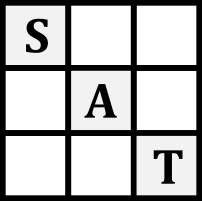

A Visual Demonstration of the SDO Analysis Toolkit (SAT).

In this exercise, we will perform an SDO analysis using the included custom classes for importing, manipulating, and plotting data. This script may serve as a basic for customized analysis, or as as quick-run validation of the installation. 

_________________________________________________

Copyright (C) 2023 Trevor S. Smith

Drexel University College of Medicine

*This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.*

*This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details.*

*You should have received a copy of the GNU General Public License along with this program.  If not, see <https://www.gnu.org/licenses/>.*

__________________________________________

## **INSTRUCTIONS**: 

Load in both *xtData.m* and *ppData.m* in the prompted order. 

%This short bit of code uses the a UI to grab the files. 
ppFile= "C:\Users\Frog\OneDrive - Drexel University\TSAnalysis\sdoAnalysis\sat-master\demoData\ppData.mat";
xtFile="C:\Users\Frog\OneDrive - Drexel University\TSAnalysis\sdoAnalysis\xtData.mat";
% -- Load data into expected format; 
xtData0 = load(xtFile); 
ppData0 = load(ppFile); 
xtfield = fields(xtData0); 
ppfield = fields(ppData0); 
xtData = xtData0.(xtfield{1}); 
ppData = ppData0.(ppfield{1}); 
% at this point, we should have variables 'xtData' and 'ppData' in the
% workspace

Create and populate instances of the *xtDataCell* and *ppDataCell* classes to operate on the time series and point-process data, respectively. 

% __ Initialize and populate an 'xtDataCell' class

xtdc = xtDataCell(); 
xtdc.import(xtData); 

% __ Initialize and populate a 'ppDataCell', class

ppdc = ppDataCell(); 
ppdc.import(ppData); 


Preprocess the *xtDataCell* and *ppDataCell* instances. 

    xtDataCell: 

- The 'discretize' method assigns a discrete integer 'state' to each recorded point of the signal envelope in *xtDataCell*. 

- While we will use default parameters here (i.e. no arguments)  for assigning 'state' from amplitude, which work well with our data, other parameters are available and should be optimized for user data. Further details about the parameters can be found on the documentation. 

    ppDataCell: 

- The 'shuffle' method generates shuffled spiketimes for the null hypotheses for shuffle spikes. 

- While we use the default parameters here (i.e. no arguments), other methods of shuffling spikes are available, and can be found in the documentation. 

%// state-map signal
xtdc = xtdc.discretize(); 
% // Shuffle Spiketimes 
ppdc.shuffle; 

### METHOD 1: Single Neuron to Single Channel

Here, we will quickly test a specific spiking unit of interest against the a specific EMG channel. 

#### Step 1.  Assign a variable with the indexed order of both the spiking unit and EMG channel. 

*You may uncomment one set of XT_CH_NO *and *PP_CH_NO* variables to reference either pair used for analysis within the paper. However, any combination (XT_CH_NO ∈ [1:11], PP_CH_NO  ∈ [1:12])  may be used in the demonstration data. 

% __ Example SMU x EMG
XT_CH_NO = 8; 
PP_CH_NO = 12; 
% __ Example IN x EMG
%XT_CH_NO = 6; 
%PP_CH_NO = 4; 

#### Step 2. Generate and populate two instances of the *pxtDataCell *class. 

This class is designed to handle the probability-type data of signal (from *xtDataCell*) sampled around spikes (from *ppDataCell*). There are other optional properties of the *pxtDataCell* method which are not set here. Refer to the documentation for additional information. 

- 'px0' refers the the pre-spike interval, of states before the spiking event. 

- 'px1' refers to the post-spike interval, of states at, and immediately after, the spiking event. 

% __ Generate pre-spike (px0) and post-spike (px1) 'pxt' classes; 
%// Prespike
px0 = pxtDataCell(); 
%// PostSpike
px1 = pxtDataCell(); 

Assign the proper properties to 'px0'. Because this *pxtDataCell* is refering the pre-spike interval, we will set the *.duraMs* property to a negative value. Here, a value of -10 corresponds to the interval t=[-10, 0) miliseconds relative to spiketime, *t*. We will use the *.import* method of the *pxtDataCell* to import the *xtDataCell* and *ppDataCell. *

px0.duraMs = -10; % Negative here to refer to data -before- spiking event; (i.e. the interval -10ms to 0ms before spike)
px0.import(xtdc, ppdc, XT_CH_NO, PP_CH_NO); 

We will only use the default properties of *pxtDataCell* for refering to the post-spike interval. Simply import *pxtDataCell* and *xtDataCell*. By default, this will evaluate the interval t=[0,+10] miliseconds relative to spiketime, *t*. 

px1.import(xtdc, ppdc, XT_CH_NO, PP_CH_NO); 

#### Step 3: Generate the *sdoMat* class and compute the SDO. 

The SDO may be calculated as a method of the *sdoMat* class, using a pre-spike and post-spike *pxtDataCell*. Generate an instance of this class and call the 'computeSdo' method while passing the pre-spike and post-spike distributions. 

Computations between a single spiking unit to a single EMG channel should be quick. 

% __ compute the sdo from the 'sdoMat' class as the difference between probability distributions; 
sdo = sdoMat(); 
%// Optional (Slower) replacement of the estimated background w/ the
%background SDO generated w/ the same algorithim.
%sdo.computeBackgroundSdo(xtdc);

sdo.computeSdo(px0, px1); 

Perfom statistical tests of the returned SDO to evaluate significance by calling the *.performStats* method. Different p-values as a threshold for signficance can be set, as a property of the *sdoMat* class. By default, p=<0.05 is used to assign significant differences of the spike-triggered SDO to null hypotheses. 

sdo.performStats; 

#### Step 4: Plot the SDO

Here, we plot the various visualizations of the SDO to gain an inference about the function of the SDO, and if these features are significantly different than the expected null hypotheses. *.plot* is a method of the *sdoMat* class. 

Plotting BI x channel36_unit2


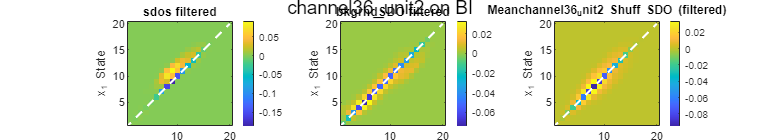

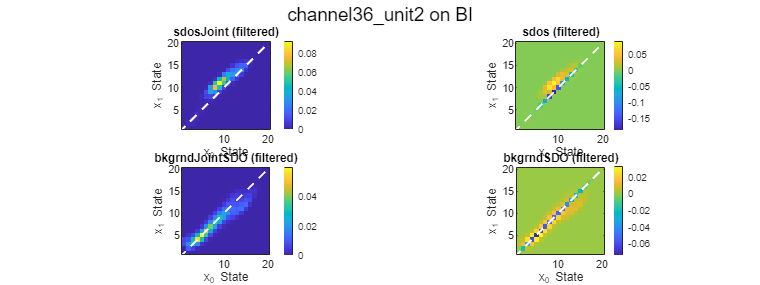

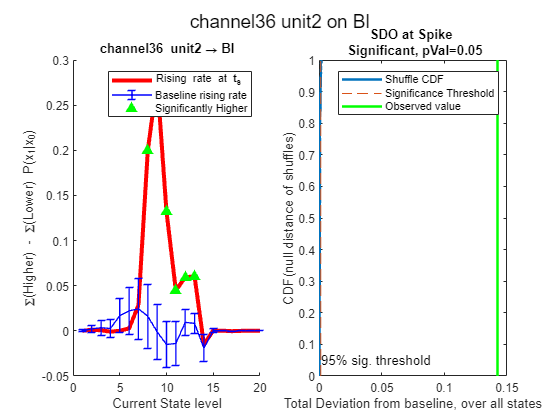

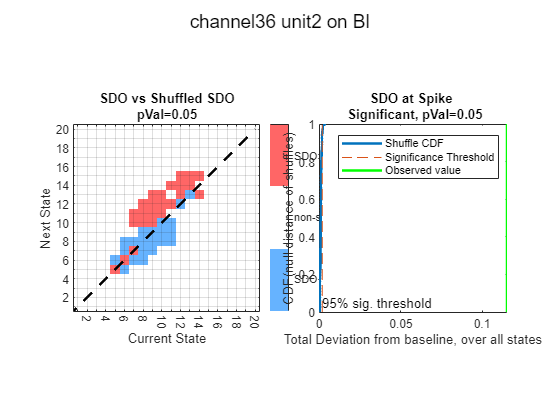

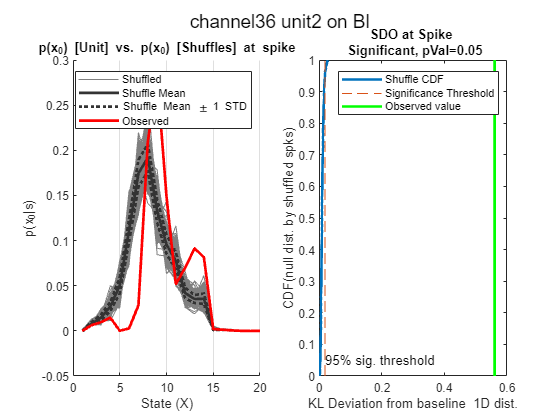

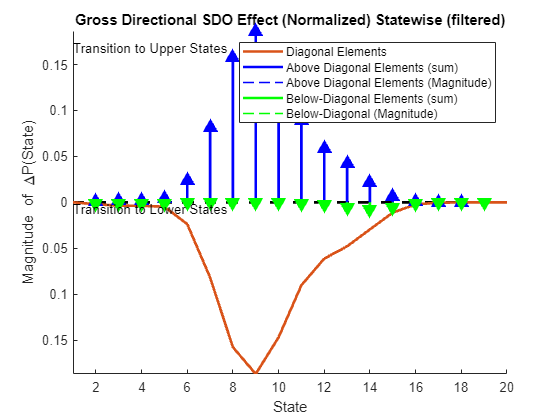

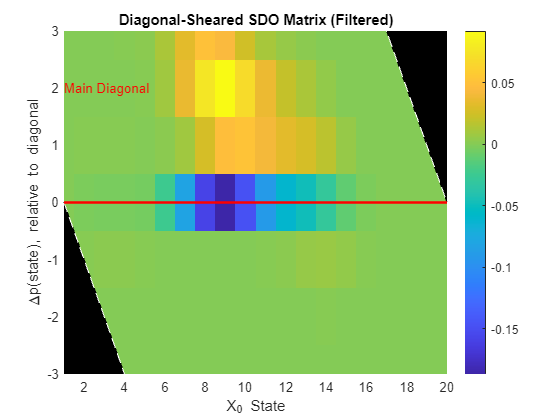

plot(sdo); 

Output Images: 

- The actual (non-normalized) SDO matrix, relative to the background and shuffled-spike SDO matrices. 

- The joint-probability distributions vs. the SDO matrices for both spike-triggered and background SDOs. 

- Significant state-dependent directional (i.e. towards higher or lower state) effects of the SDO, relative to the shuffled-spike null SDOs. 

- Significant state-to-state transitions (pixels), relative to the shuffled-spike null SDOs. 

- Significant differences in the pre-spike state distribution (i.e. p(x0)), relative to the shuffled-spike null SDOs. (Spike-tuning)

- Quiver SDO: Summary of the weighted directional effects (i.e. towards higher or lower states) of the SDO. 

- Shear SDO: Condensed form of the SDO which emphasizes the elements near the main-diagonal (now on the horizontal). 

Further interpretation of these images can be found in both the paper and the documentation. 

#### Step 5: Use the SDO to predict post-spike signal state distributions

Here, we show the use of the SDO for predicting the distributions of states immediately after spike. We use a number of null hypotheses for testing the utility of the SDO for predictions, including the Spike-triggered average (STA). These hypotheses are described using a transition matrix of the form: 


$$\hat{p\left(x_1 \right)} =A\;p\left(x_0 \right)$$


Where the predicted post-spike distribution is given by premultiplication of the the prespike distribution with the appropriate transition matrix.

Generate transition matrices 

% __ Make transition Matrices from the 'sdoMat' class
sdo.makeTransitionMatrices(); 

Using Estimated (non-exact) Background


Capture a third instance of *pxtDataCell* which contains the predicted post-spike distribution created using the *.getPredictionPxt* method of the *sdoMat* class, passing the pre-spike *pxtDataCell*, 'px0', as the input. 

This instance contains the predicted post-spike output from all seven hypotheses, including the SDO. 

% __ Predict a probability distribution from the 'sdoMat' class from an
% initial probability distribution; 
pd_px1 = sdo.getPredictionPxt(px0); 

Test the accuracy of the predicted post-spike state distributions using the actual/observed distributions. Here, we will use the *.compare_pxt* method of *pxtDataCell* to measure the prediction error. Pass the observed values/ground truth as the input argument. The significance of any differences in the predictions are assessed using 1000-shuffle bootstrapping of observed spiking events. 

% __ Compare predictions relative to observed post-spike probability
% distributions; 
pd_px1.comparePxt(px1); %compare against post-spike interval

Finally, visualize the errors using the *.plotError *method of *pxtDataCell*. 

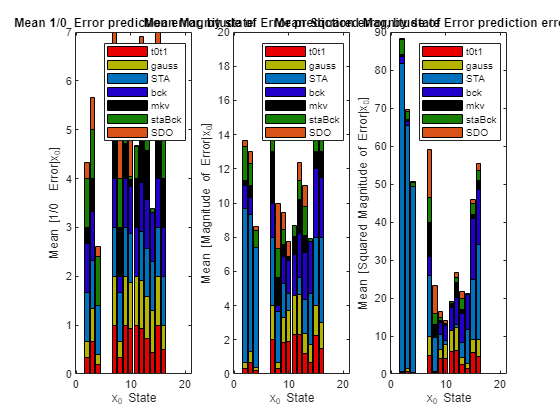

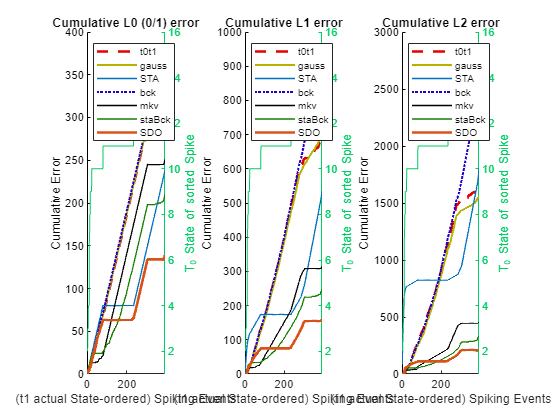

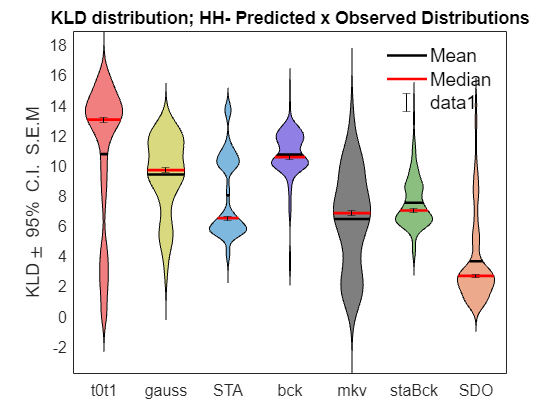

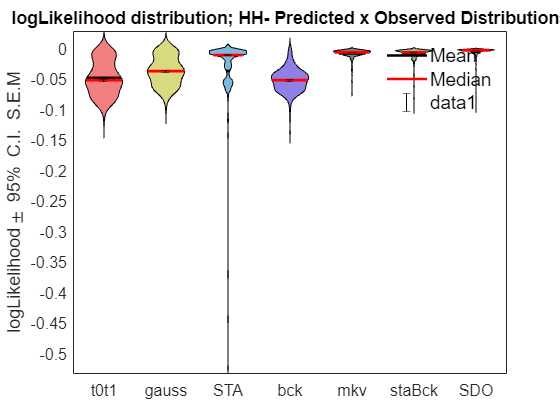

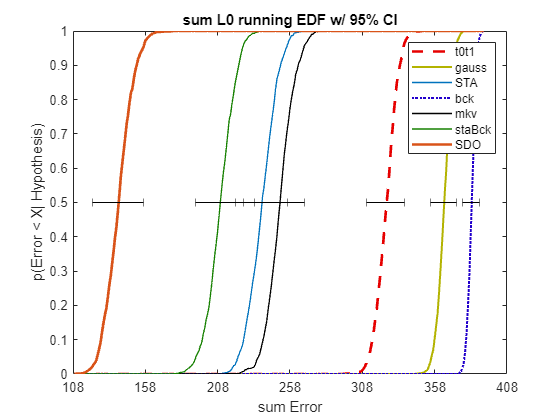

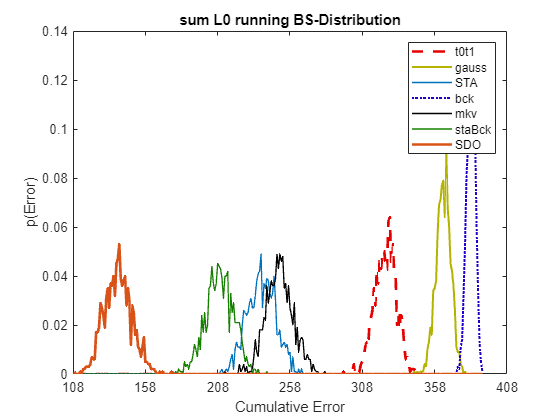

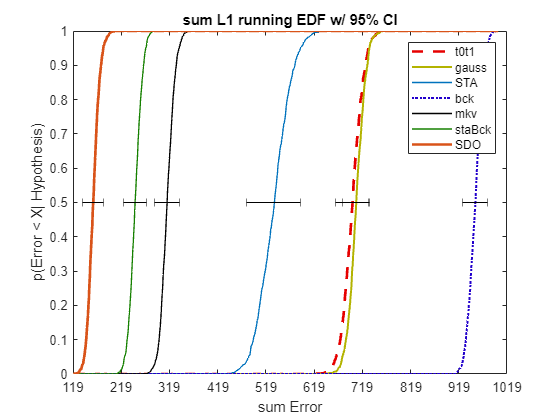

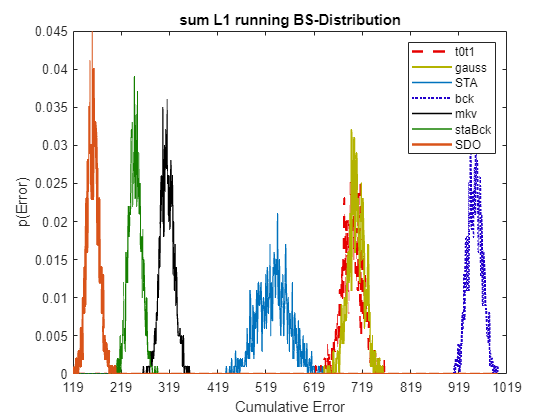

% __ Plot prediction errors between the two 'pxt' classes; 
pd_px1.plotError; 

Multiple windows will pop up: 

- Stacked-bar chart of state-dependent error rates, by hypothesis. (Lower is better)

- State-ordered errror rates, by hypothesis. (Lower is better)

- Kullback–Leibler Divergence (KLD) between predicted and observed *distributions* of post-spike state. (Lower is better). 

- Log-Likelihood between predicted and observed *distributions* of post-spike state (Higher is better). 

- Empirical Distribution Function (EDF) of bootstrapped occurrence of error (E0), by hypothesis. 

- Distribution of bootstrapped occurrence of error (E0), by hypothesis.

- Empirical Distribution Function (EDF) of bootstrapped magnitude of error (E1), by hypothesis. 

- Distribution of bootstrapped magnitude of error (E1), by hypothesis.

- Empirical Distribution Function (EDF) of median Kullback–Leibler Divergence (KLD) across bootstrapped distributions. (Lower is better)

- Distribution of median Kullback–Leibler Divergence (KLD) across bootstrapped distributions. (Lower is better)

- Empirical Distribution Function (EDF) of median Log-Likelihood across bootstrapped distributions. (Higher is better)

- Distribution of median Log-Likelihood across bootstrapped distributions. (Higher is better)

### METHOD 2: Multiple-Comparisions

Here, we will use the *sdoMultiMat* class to build SDOs between all combinations of spiking signal in *ppDataCell* and EMG in *xtDataCell* using a common set of parameters. Overall, this takes longer than Method 1, but is easier for the user, and can be used to screen for significance of individual combinations. 

The total duration will depend on the number of combinations to be computed. Large numbers of SDOs (> 2 Million) may a long time. Recall that 1000 shuffled-spikes SDOs are generated for each combination, by default. 

#### Step 1: Generate an instance of *sdoMultiMat*

smm = sdoMultiMat; 

#### Step 2: Compute all SDO combinations

Using the* .compute* method of the *sdoMultiMat*, pass the generated *xtDataCell* and *ppDataCell*. 

We will only use the default parameters here. Different parameters may be selected instead using different properties of the *sdoMultiMat* class. 

As each channel is completed, it will push an output message to the terminal. This can be used to estimate the overall duration. (Use the *.subsample* method of *xtDataCell* and *ppDataCell* to generate subsets of these dataCells instead). 

smm.compute(xtdc, ppdc); 

Elapsed time is 25.915003 seconds.
Finished Ch#1/11
Elapsed time is 24.621588 seconds.
Finished Ch#2/11
Elapsed time is 24.839017 seconds.
Finished Ch#3/11
Elapsed time is 25.117758 seconds.
Finished Ch#4/11
Elapsed time is 24.045495 seconds.
Finished Ch#5/11
Elapsed time is 23.056591 seconds.
Finished Ch#6/11
Elapsed time is 24.039357 seconds.
Finished Ch#7/11
Elapsed time is 25.103487 seconds.
Finished Ch#8/11
Elapsed time is 24.727889 seconds.
Finished Ch#9/11
Elapsed time is 26.084067 seconds.
Finished Ch#10/11
Elapsed time is 24.975865 seconds.
Finished Ch#11/11


#### Step 3: Screen Combinations for Significance

To quickly identify interesting combinations of spike and signal, use the *.findSigSdos* method of the *sdoMultiMat* class. 

smm.findSigSdos(); 

sigMat = smm.sigMat; %extract property as a variable; 

Here, the property 'sigMat' is a *struct* containing both the names (strings) and the indexed positions (in *ppDataCell* and *xtDataCell*) of signifcant SDOs, and the number of individual tests on the matrices which returned a significant p-value (as set in the *sdoMultiMat *property). These SDOs are more likely to be interesting for prediction and analysis. 

NOTE: SDOs which are generated by very few numbers of spikes (n < 200) have a higher false-positive rate when evaluating significance in the SDO matrix (i.e. With a fewer number of observations, it is more likely that the empirical distribution diverges from the actual sample distribution). As with the STA, caution should be taken when interpreting from these SDOs. 

#### Step 4: Plot Prospective SDOs

Use the *.plot* method of *sdoMultiMat* class to directly plot a prospective SDO. 

(Here, we will use the same indicies as used in Method 1 to directly compare)

smm.plot(XT_CH_NO, PP_CH_NO); 

NOTE: Here, the 'background' SDO is calculated using ALL time points in the *xtDataCell* channel, and is more accurate than the approximation used in Method 1 (which estimates the background SDO from the covariance of signal state). Thus, there may be slight differences in the background SDO projected in Method 1 and Method 2. (The true background can be restored in Method 1 using the *.computeBackground* method for *pxtDataCell*, but this takes additional time and is rarely significant). 

#### Step 5: Extract SDOs for further Analysis

Use the *.extract* method of *sdoMultiMat* to return a *sdoMat* object. This object can then be manipulated as in Method 1 (e.g., generating predictions of state). 

ss = smm.extract(XT_CH_NO, PP_CH_NO); 

% cleanup unnecessary variables from workspace
clear xtFile fdir1 ppFile xtData0 ppData0